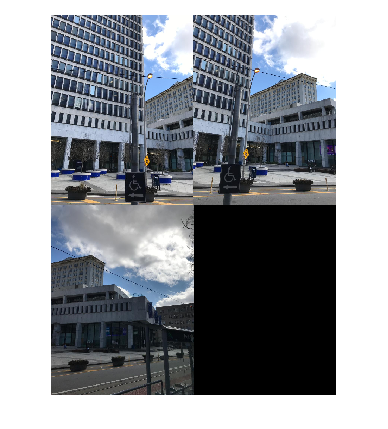

buildingDir = fullfile("GSU/");
buildingScene = imageDatastore(buildingDir);

montage(buildingScene.Files)

I = readimage(buildingScene,1);
grayImage = im2gray(I);
points = detectSURFFeatures(grayImage);
[features, points] = extractFeatures(grayImage,points);

numImages = numel(buildingScene.Files);
tforms(numImages) = projective2d(eye(3));

imageSize = zeros(numImages,2);

for n = 2:numImages

    pointsPrevious = points;
    featuresPrevious = features;

    I = readimage(buildingScene, n);

    grayImage = im2gray(I);    

    imageSize(n,:) = size(grayImage);

    points = detectSURFFeatures(grayImage);    
    [features, points] = extractFeatures(grayImage, points);

    indexPairs = matchFeatures(features, featuresPrevious, 'Unique', true);
       
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        

    tforms(n) = estimateGeometricTransform2D(matchedPoints, matchedPointsPrev,...
        'projective', 'Confidence', 99.9, 'MaxNumTrials', 2000);

    tforms(n).T = tforms(n).T * tforms(n-1).T; 
end

% Compute the output limits for each transform.
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);    
end

avgXLim = mean(xlim, 2);
[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

Tinv = invert(tforms(centerImageIdx));
for i = 1:numel(tforms)    
    tforms(i).T = tforms(i).T * Tinv.T;
end

for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
end

maxImageSize = max(imageSize);

xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([height width 3], 'like', I);

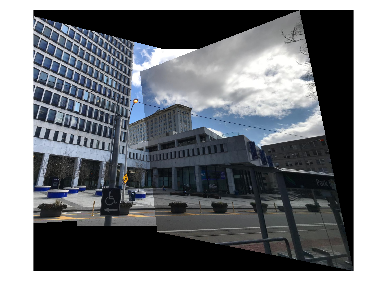

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

for i = 1:numImages
    
    I = readimage(buildingScene, i);   

    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
  
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);

    panorama = step(blender, panorama, warpedImage, mask);
end

figure
imshow(panorama)